close all;

%setup for N and x_n
N = 6;
n = 0:1:N-1;
x_n = transpose(cos((pi./3).*n));


%find fourier transform
X_k = myfft(x_n)

X_k =   -0.0000 + 0.0000i
   3.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   3.0000 + 0.0000i



x_n_recon = myifft(X_k)

x_n_recon =    1.0000 + 0.0000i
   0.5000 + 0.0000i
  -0.5000 + 0.0000i
  -1.0000 + 0.0000i
  -0.5000 + 0.0000i
   0.5000 + 0.0000i




error = sum(abs(x_n_recon - x_n)) %e-15 error need to check if thats acceptable

error = 3.1793e-15

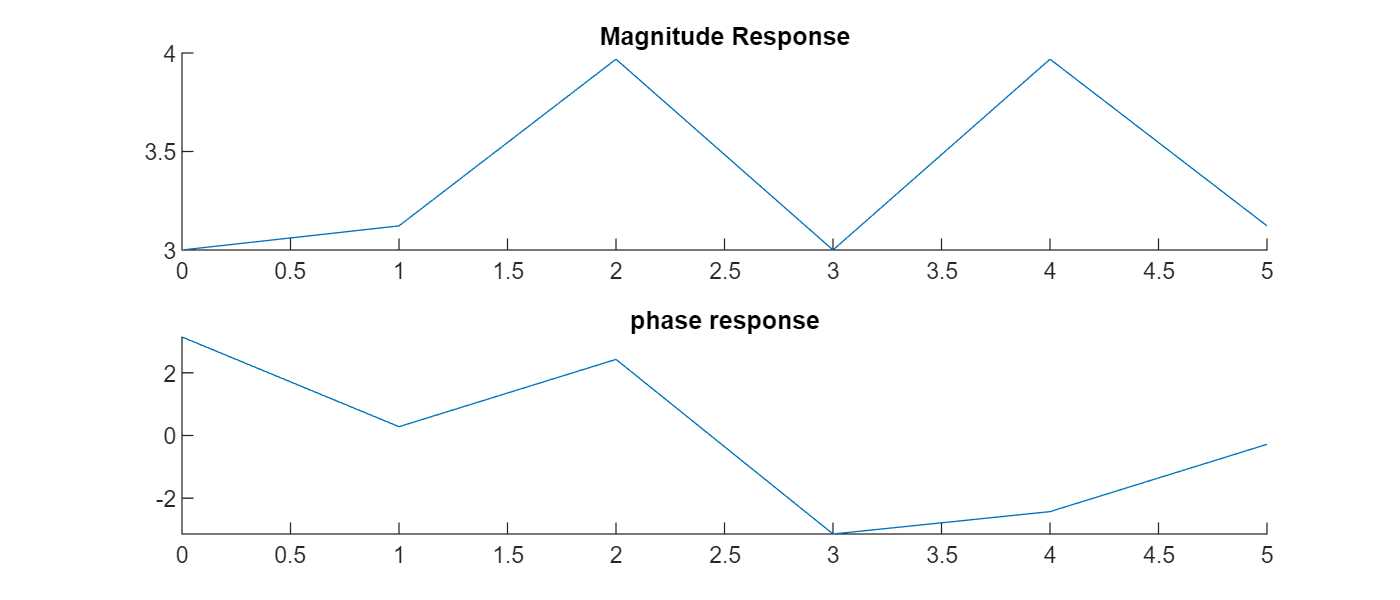


N=6;
n=0:N-1;
x_n2 = transpose(cos(pi/3*n).*(n-1));
x_jw2 = myfft(x_n2);
xr2=myifft(x_jw2);

f2 = figure('Position', [1,1,700,300]);
subplot(2,1,1);
hold on
title('Magnitude Response');
plot(n,abs(x_jw2));
subplot(2,1,2);
hold on
title('phase response')
plot(n,angle(x_jw2));